# RATE CONTROLLER EXTENDED DESIGN APPROACH

clc
clearvars

set(0, 'DefaultFigureWindowStyle', 'normal');
addpath(genpath('.'))
[opt_time, opt_bode, opt_nichols] = setPlots;

run Stab_Simple_Simscape__Init.m;

## System Properties

### Gimbals

J = params.Plant.payloadJ; % Payload Inertia
n = params.Plant.gearRatio; % Gear Ratio
Jn = J/n^2;
Plant = tf(1, [Jn 0]);
Plant.Name = '1/Js';
Kt = params.Plant.motorKT;

### Gyro

sensorBW = params.Gyro.f_bw;
Sensor = tf((2*pi*sensorBW)^2, [1 2*0.5326*(2*pi*sensorBW) (2*pi*sensorBW)^2]);
Sensor.Name = 'Sensor no Delay';

Sensor_d = Sensor;
Sensor_d.IODelay = params.Gyro.dtClock*params.Gyro.cycle_delay;
Sensor_d.Name = sprintf('Sensor with %.2f [cycles] Delay', params.Gyro.cycle_delay);

### Sensor View

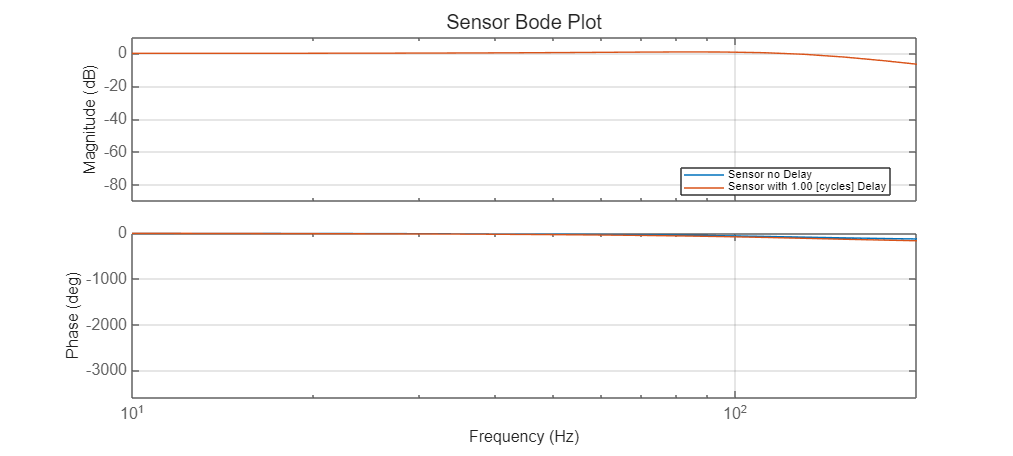

figure('Units','normalized','Position',[0 0 1.0 0.8]);
bodeplot(Sensor, Sensor_d,opt_bode);
xlim([10 200])
title('Sensor Bode Plot');
legend('show', 'Location','best');

## Controller Design

### Initial View

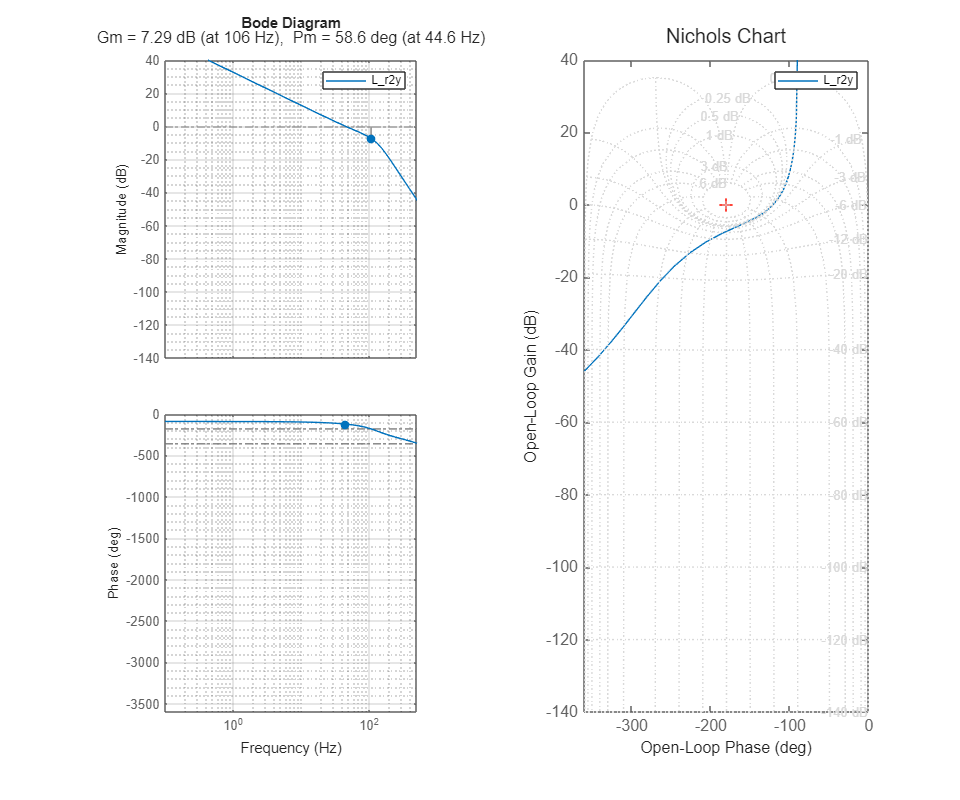

initial_design = get_design_functions(0.02/n^2, Kt, Plant, Sensor_d*n, 1);
plot_control_design(initial_design, 1, 0, 0)

### Step1 - Lag Controller

f_LAG = 40.6;
% Kp = 0.05;
Kp = 0.015/n^2;

C_LAG = Kp*tf([1 (2*pi*f_LAG)], [1 0]);
C_LAG.Name = 'Lag Controller';
design_Step1 = get_design_functions(C_LAG, Kt, Plant, Sensor_d*n, 1);

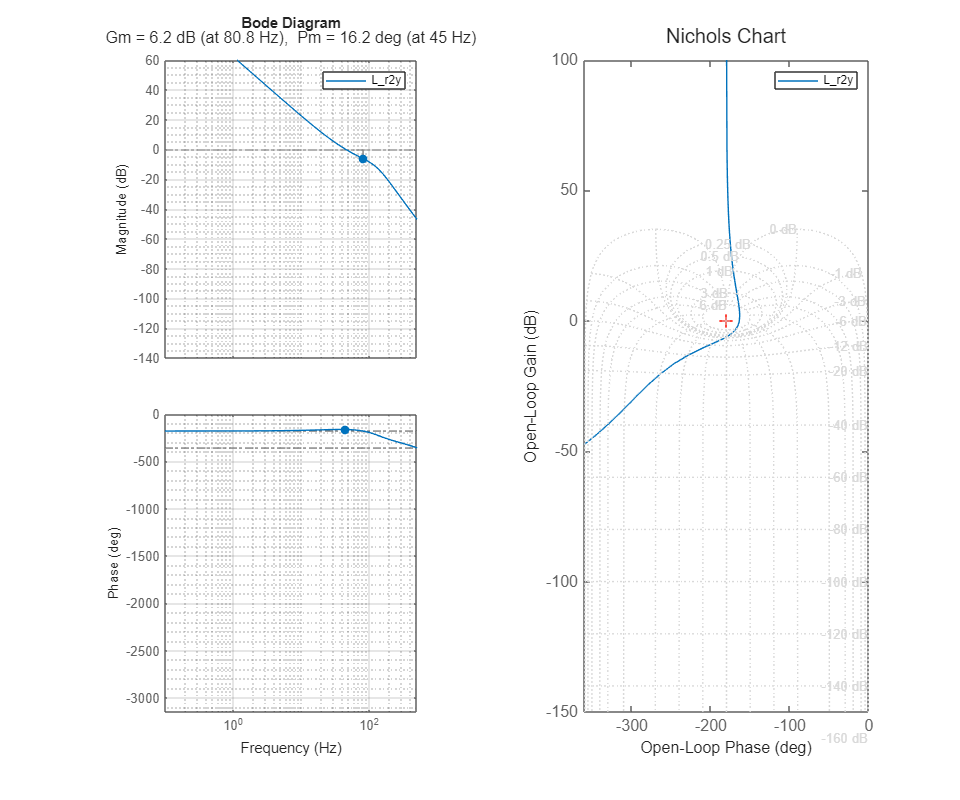

plot_control_design(design_Step1, 1, 0, 0)

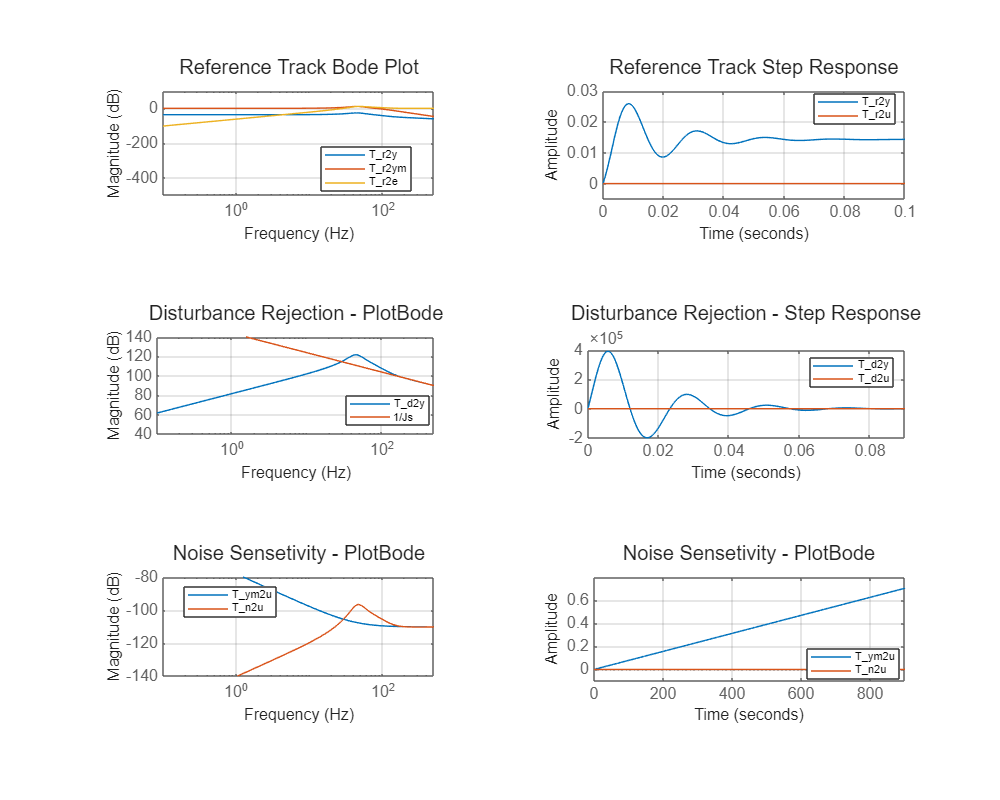

plot_control_design(design_Step1, 0, 1, 0)

### Step2 - Lead Filter

f_LEAD = 125.2;
phiM_Deg = 40;

a = (1 + sind(phiM_Deg))/(1 - sind(phiM_Deg));
sqa = sqrt(a);

C_LEAD = tf([a sqa*(2*pi*f_LEAD)], [1 sqa*(2*pi*f_LEAD)]);
% C_LEAD = tf(1, [1]);
C_LEAD.Name = 'Lead Compensator';
design_Step2 = get_design_functions(C_LAG, Kt, Plant, Sensor_d*n, C_LEAD);

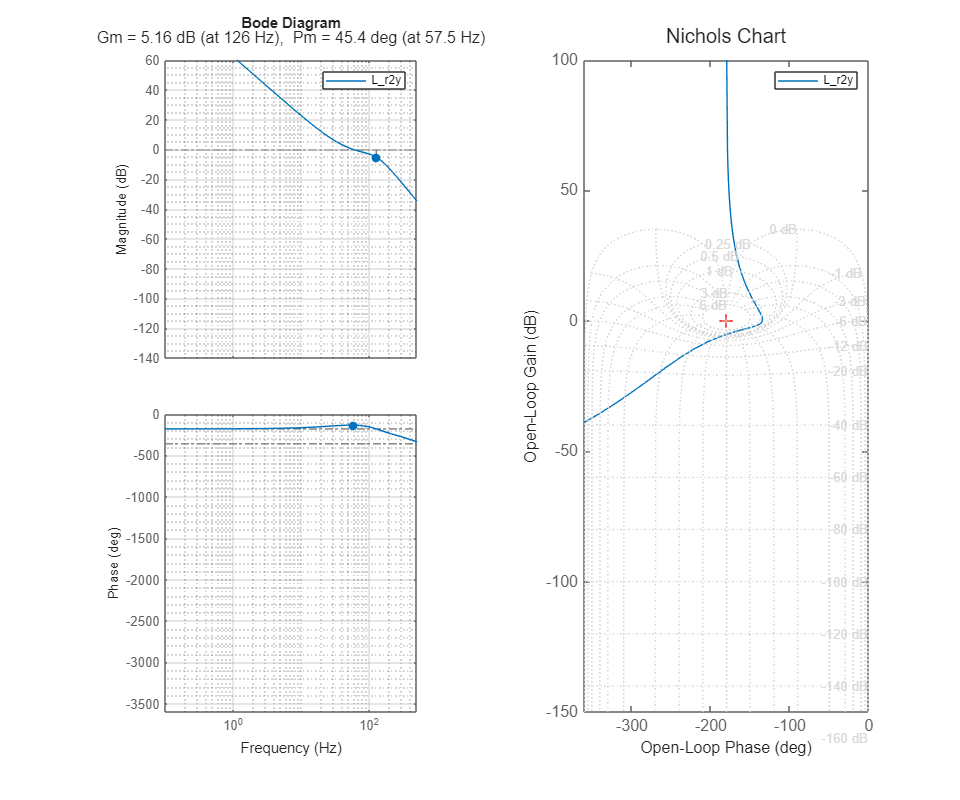

plot_control_design(design_Step2, 1, 0, 0)

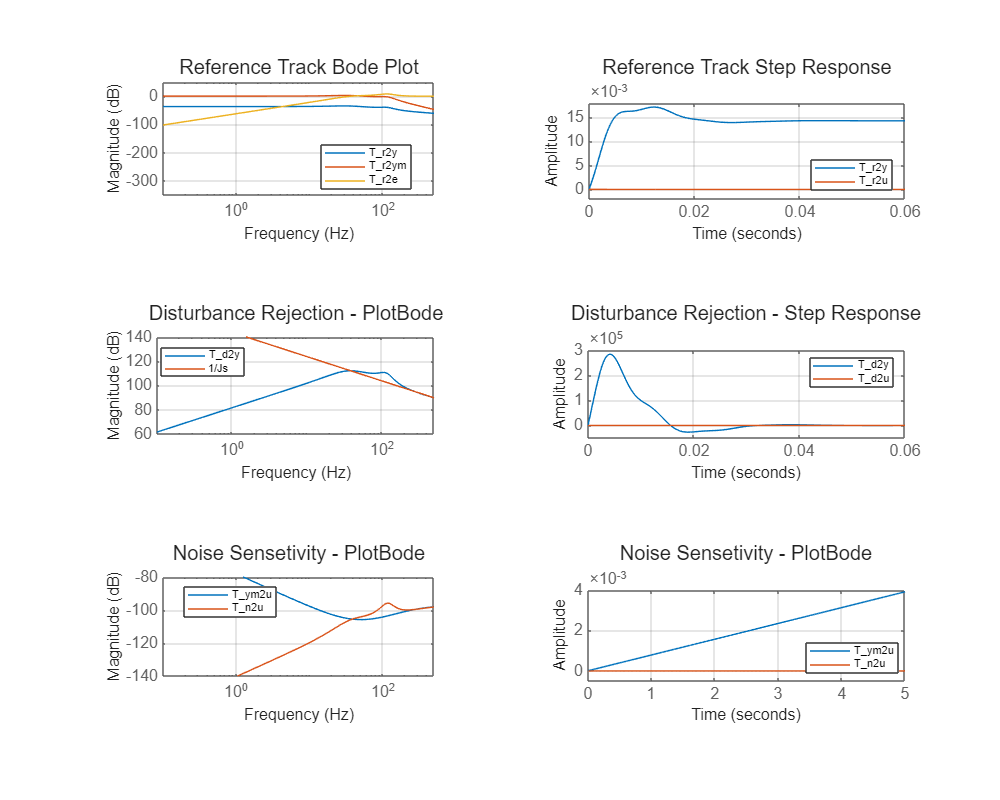

plot_control_design(design_Step2, 0, 1, 0)

## Accounting for uncertain parameters 

% Kt_unc = ureal('kt_unc', Kt, 'percent', 10);
% J_unc = ureal('J_unc', J, 'percent', 5);
% 
% Plant_unc = tf(1, [J_unc 0]);
% Plant_unc.Name = '1/J_{unc}';

% design_Step2_unc = get_design_functions(C_LAG, Kt_unc, Plant_unc, Sensor_d, C_LEAD);
% plot_control_design(design_Step2_unc, 1, 1, 0)

Error using xlim (line 37)
Invalid or deleted object.

Error in plot_control_design (line 28)
    xlim([-360 0])

### Going Parameters

[z,p,k] = zpkdata(C_LAG);
zpk(z,p,k, 'DisplayFormat', 'roots')


ans =
 
  3.0612e-06 (s+255.1)
  --------------------
           s
 
Continuous-time zero/pole/gain model.
Model Properties


[z,p,k] = zpkdata(C_LEAD);
zpk(z,p,k, 'DisplayFormat', 'timeconstant')


ans =
 
  (1+0.002726s)
  --------------
  (1+0.0005928s)
 
Continuous-time zero/pole/gain model.
Model Properties


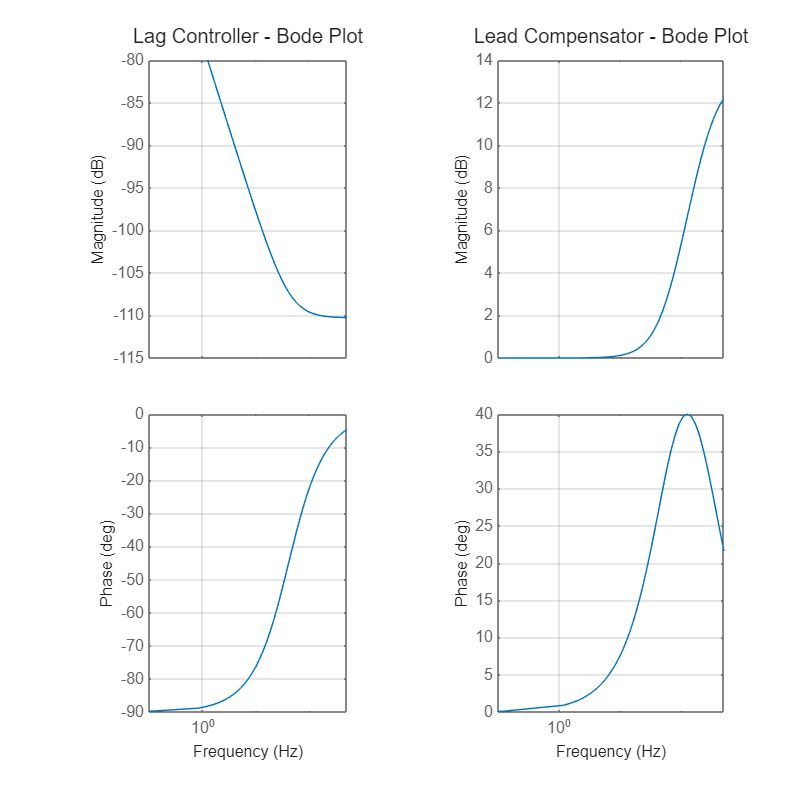

plot_control_design(design_Step2, 0, 0, 1)

## Compare Designs


figure('Position',[0 0 1200 500])

subplot(1,3,1:2)
bodeplot(design_Step2.L,design_prev.L, opt_bode)
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 12)
xlim([1e-3 1e3])
legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)

subplot(1,3,3)
nicholsplot(design_Step2.L, design_prev.L, opt_nichols)
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)
xlim([-360 0])

figure('Position',[0 0 1200 500])

subplot(1,2,1)
b1 = bodeplot(design_Step2.T_r2y,design_prev.T_r2y, opt_bode);
b1.PhaseVisible = 'off';
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide)

subplot(1,2,2)
stepplot(design_Step2.T_d2y,design_prev.T_d2y, opt_nichols);
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide)

figure('Position',[0 0 800 500])

b1 = bodeplot(design_Step2.T_d2y,design_prev.T_d2y, opt_bode);
b1.PhaseVisible = 'off';
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide)